clear all;
clc;
%      Første model brugt
s = tf('s');

%% Question 2 
% Vc is the voltage across the capacitor, Vi
% is the source voltage, R is
% the resistance (50Ω), and C is the capacitance (160F). Which of the following
% statements is FALSE?
R=50   %Ohm 

R = 50

C=160  %Farad

C = 160


num = 1/R*C;
den = s + (1/R*C);
G= num/den

G =
 
    3.2
  -------
  s + 3.2
 
Continuous-time transfer function.
Model Properties


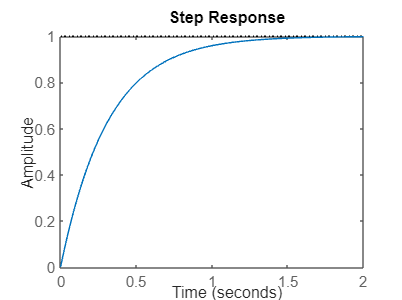

step(G)

stepinfo(G)

ans = struct with fields:
         RiseTime: 0.6866
    TransientTime: 1.2225
     SettlingTime: 1.2225
      SettlingMin: 0.9045
      SettlingMax: 0.9993
        Overshoot: 0
       Undershoot: 0
             Peak: 0.9993
         PeakTime: 2.2882


## qustion 3

P = 10/(s^2+10^2)

P =
 
     10
  ---------
  s^2 + 100
 
Continuous-time transfer function.
Model Properties


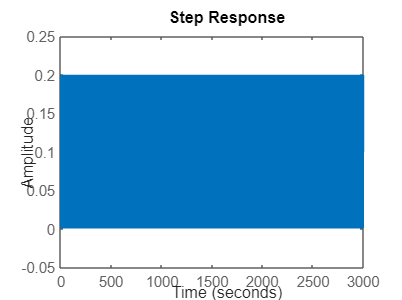

step(P)

J = 10/(s^2+2*10*s+10^2)

J =
 
         10
  ----------------
  s^2 + 20 s + 100
 
Continuous-time transfer function.
Model Properties


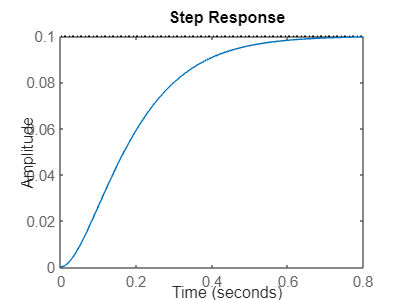

step(J)

## question 4

clear all;
clc;
%      Første model brugt
s = tf('s');

G= (s-10)/(s^2+10)

G =
 
   s - 10
  --------
  s^2 + 10
 
Continuous-time transfer function.
Model Properties


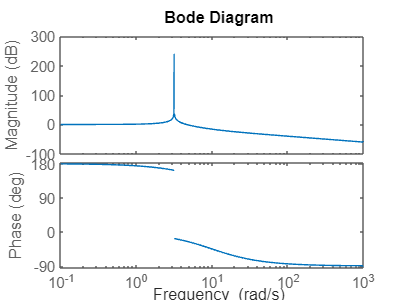

%lektion 6 side Closed loop repsonse. 
bode(G)

pole(G)

ans =    0.0000 + 3.1623i
   0.0000 - 3.1623i


zero(G)

ans = 10

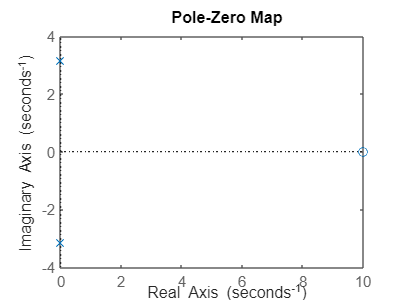


pzplot(G)


% svaret er 4 Husk at se på grafen og se ligningen for spg 3 


## qustion 5

clear all;
clc;
%      Første model brugt
s = tf('s');
% 5. Q5. The Bode plot diagrams of the magnitude and phase of a transfer function G(s)
% of a linear system is shown in Fig. 2
% her skal jeg aflæse et bode plot og finde hvad det korrekt svar er. 

%k0 (Knul) er DC gain når freq=0
% Der er fald på 20db på en decade
% DC gain er = 5.94 DB. 
% Phasen er ved 0db 165
% omkring 10^0 er den på 45grader.

%1 - og + reelle poler 0 nuller
%2 - 1 negativ real pole og 1 negativ zero
%3 - 1 positiv real pol og nul zero
%4 - complexpol og 1 reelt zero
%5 - positive real poler og 1 positivt real nul 

w=0.104

w = 0.1040

ph=165

ph = 165

Kss=5.94

Kss = 5.9400



Ga = (s-2)/((1+s)^2)

Ga =
 
      s - 2
  -------------
  s^2 + 2 s + 1
 
Continuous-time transfer function.
Model Properties


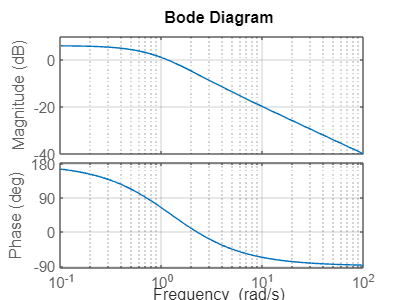

bode(Ga)
grid on;

## Q 6 


clear all;
clc;
%      Første model brugt
s = tf('s');
K=1

K = 1

G = K/(s*(s+21));
PM = 40;
Phi_G = PM - 180;
omegac = rad2deg(2.28);
bode(G);
[magKv,PhaseKv] =bode(G,omegac);
Kv_P=1/magKv;


K01=0.1

K01 = 0.1000

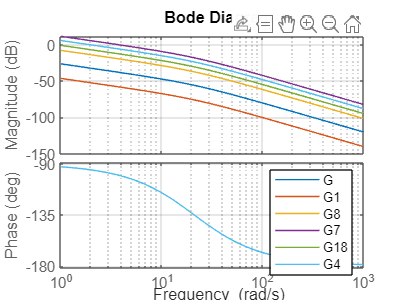

G1 = 0.1/(s*(s+21));
G8 = 8.4/(s*(s+21));
G7 = 77.5/(s*(s+21));
G18 = 18.5/(s*(s+21));
G4 = 40/(s*(s+21));

hold on;
legend;
bode(G1)
bode(G8)
bode(G7)
bode(G18)
bode(G4)
grid on;
hold off; 

## Q7

% er det bare mag til db 
jk=mag2db(2)

jk = 6.0206

## q8


clear all;
clc;
%      Første model brugt
syms s
solution = solve( 5*s^2+s+0.5==0,s)

$$solution = \left(\begin{array}{c} -\frac{1}{10}-\frac{3}{10}\,\mathrm{i}\\ -\frac{1}{10}+\frac{3}{10}\,\mathrm{i} \end{array}\right)$$

## Q11

clear all;
clc;
%      Første model brugt
s = tf('s'); % den var -0.1639 og den skal have skiftet fortegn

KM = 1/(0.1639)

KM = 6.1013

KMDB=mag2db(KM)

KMDB = 15.7084

## q12

clear all;
clc;
%      Første model brugt
s = tf('s');
KM = 1/(0.0222)

KM = 45.0450

wn=sqrt(45)
G=45/(s^2+2*

Invalid expression. When calling a function or indexing a variable, use parentheses. Otherwise, check for mismatched delimiters.

G =
 
            45
  ----------------------
  91125 s^2 - 4.101e05 s
 
Continuous-time transfer function.
Model Properties


pole(G)

ans =          0
    4.5000
